data = importdata("data.txt")

data =      1
     5
     7
     9
    11
    15
    17
    19
    23
    23


settings = importdata("settings.txt")

settings =     0.0134
    0.0110


time = (1:length(data))*settings(1)

time =     0.0134    0.0268    0.0402    0.0536    0.0670    0.0804    0.0938    0.1072    0.1206    0.1340    0.1474    0.1608    0.1742    0.1876    0.2010    0.2144    0.2278    0.2412    0.2546    0.2680    0.2814    0.2948    0.3082    0.3216    0.3350    0.3484    0.3618    0.3752    0.3886    0.4020    0.4154    0.4288    0.4422    0.4556    0.4690    0.4824    0.4958    0.5092    0.5226    0.5360    0.5494    0.5628    0.5762    0.5896    0.6030    0.6164    0.6298    0.6432    0.6566    0.6700


V = data*settings(2)

V =     0.0110
    0.0550
    0.0770
    0.0990
    0.1210
    0.1650
    0.1870
    0.2090
    0.2530
    0.2530


[U, it_max] = max (V(:))

U = 2.7170

it_max = 384

t_max = time(it_max)

t_max = 5.1456

Tz = t_max

Tz = 5.1456

Tr = time(length(time))-Tz

Tr = 6.8876

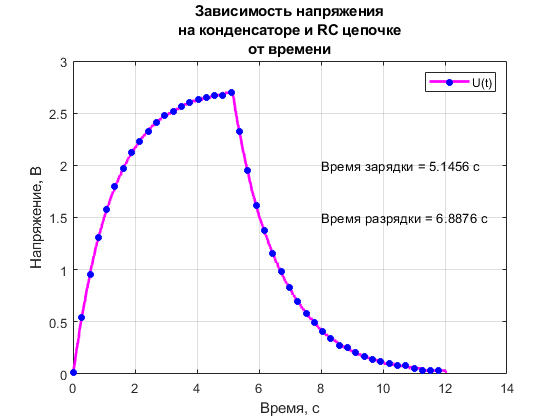

figure('Name', 'Александра Грицких, Б03-008', 'NumberTitle', 'off')
plot(time, V, 'm-*', 'LineWidth', 2, 'MarkerSize',5, 'MarkerEdgeColor','blue', "MarkerIndices", 1:20:length(time))
grid on
title({'Зависимость напряжения'; 'на конденсаторе и RC цепочке'; 'от времени'})
xlabel("Время, с")
ylabel("Напряжение, В")
legend('U(t)')
text(8, 2,['Время зарядки = ' num2str(Tz) ' c'])
text(8, 1.5,['Время разрядки = '  num2str(Tr) ' c'])
set(gcf, "Visible", "on")
saveas(gcf, "capacitor.png")
saveas(gcf, "capacitor.svg")